# Working with CSV files

Import CSV as matrix. readmatrix auromatically detects the numbers, and leaves out text headers.

readmatrix() imports the data as doubles, and can be directly worked with as vectors.

readtable() imports the data as a table type, so conversion is necessary before working the numbers. The table can be converted to numbers with **table2array().**

### **readmatrix()**

clear
clf

weekend = "C:\Users\Anders Eriksen\Documents\STM32CubeIDE Workspace\N32-HYT271\SHT45-widget\dist\RH_plotter\weekend-data.csv";
connections = "C:\Users\Anders Eriksen\Documents\STM32CubeIDE Workspace\N32-HYT271\SHT45-widget\dist\RH_plotter\playing-with-connections.csv";
hmm = "C:\Users\Anders Eriksen\Documents\STM32CubeIDE Workspace\N32-HYT271\SHT45-widget\dist\RH_plotter\2025-09-12-1600.csv";
path = hmm;
graphs = 2;

opts1 = detectImportOptions(path);

### readtable()

source1_csv = readtable(path, opts1);


data = table2array(source1_csv);
data_header = string(opts1.VariableNames);

### Plot data

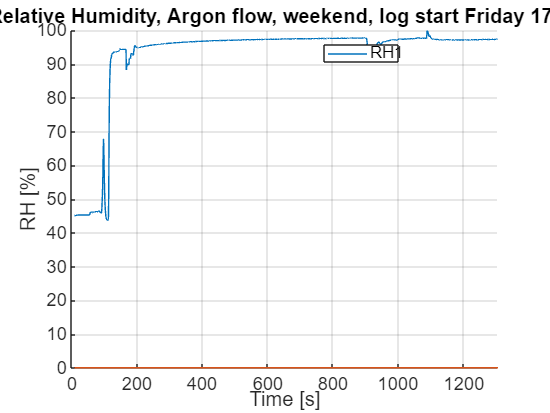

fig_num = 0;

fig_num = fig_num + 1;
fig = figure(fig_num);
clf(fig)
hold on
grid on
title('Relative Humidity, Argon flow, weekend, log start Friday 17:00')
for i = 2:(graphs+1)
    plot(data(190:end, 1),data(:, i))
end
%ylim([93, 101])
xlim([190, length(data(:, 1))])
xlabel('Time [s]')
ylabel('RH [%]')
legend(data_header(2), "Position", [0.5896 0.8510 0.1357, 0.0429])
hold off

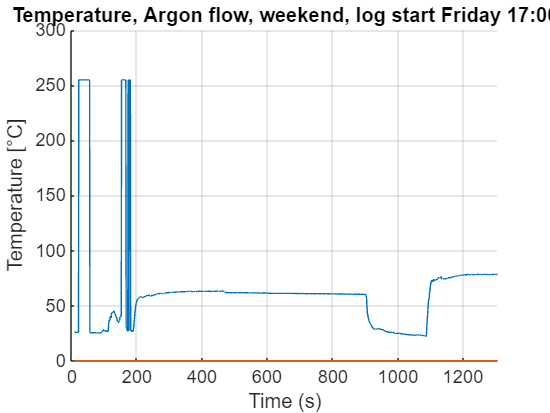

fig_num = fig_num + 1;
fig = figure(fig_num);
clf(fig);
hold on
grid on
title('Temperature, Argon flow, weekend, log start Friday 17:00')
for i = 6:(graphs + 5)
    plot(data(:, 1), data(:, i))
end
xlim([0, length(data(:, 1))])
xlabel('Time (s)')
ylabel('Temperature [°C]')
%legend(data_header(6))
hold off